# REDES NEURONALES PARA CLASIFICACIÓN

En este ejemplo de utilización de redes neuronales para clasificación se trabajará con el conjunto de datos de flores Iris de Ronald Fisher.

Fisher midió cuatro características de 50 ejemplares de tres especies Iris, largo y ancho de los sépalos y largo y ancho de los pétalos. Con este conjunto de medídas, en centímetros, Fisher desarrolló un modelo de clasificador lineal para distinguir entre las tres especies: setosa, versicolor y virginica.

# 1) Carga de los datos de flores Iris obtenidos por Ronald Fisher

Primero se cargan los datos en el espacio de trabajo de Matlab, ejecutando la siguiente instrucción en la ventana de comandos. Tras ejecutarla, aparecen las variables 'caracteristicas'  y 'clasificacion' en el espacio de trabajo. 

carga_datos_visualizacion

**¿Qué información contienen esas dos variables?**

*(ESCRIBE TU RESPUESTA AQUI)*

# 2) Visualización de los datos: ¿De qué manera podemos clasificar visualmente los datos en base a las características?

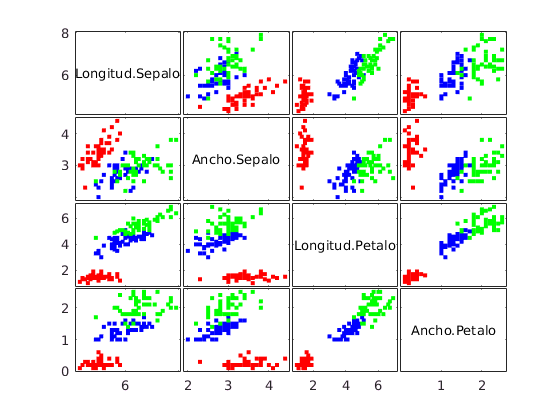

figure(1)
gplotmatrix(caracteristicas, [], clasificacion, ['r', 'b', 'g'],[],[],'off','variable',{'Longitud.Sepalo','Ancho.Sepalo','Longitud.Petalo','Ancho.Petalo'}); % Hacemos un plot enfrentando a todas las características


**¿Qué dos características eligirías para distinguir entre especies de Iris? ¿Cuál sería la peor elección?**

## *(ESCRIBE TU RESPUESTA AQUI)*

# 3) Creación y entrenamiento de la red neuronal para clasificación de flores Iris

En la sección anterior nos familiarizamos con los datos. Hemos visto que los objetos del mundo real pueden ser representados por características que los definen. Además estos objetos del mundo real los dividimos en clases.

## 3.1) Definición de la red

hiddenLayers=[10, 10, 10];
learning_rate=0.001;
epochs=10000;
red = define_red(hiddenLayers,learning_rate,epochs);
view(red);

Describe la red, ¿cuántas capas ocultas tiene? ¿cuántas neuronas cada capa?

## 3.2) Entrenamiento de la red

carga_datos_entrenamiento; % Cargamos los datos de entrenamiento. 
[red_entrenada,info_entrenamiento] = entrena_red(red,caracteristicas,clasificacion);

dsfa

## 3.3) ¿Cuál es la precisión de la red al clasificar?

caracteristicas_test=caracteristicas(:,info_entrenamiento.testInd);
clasificacion_test=clasificacion(:,info_entrenamiento.testInd);
clasificacion_test_red=red_entrenada(caracteristicas_test);
performance = perform(red_entrenada,clasificacion_test,clasificacion_test_red);
precision=evalua_red(clasificacion_test,clasificacion_test_red);

accuracy = 95.6522

¿Cuá es el significado de este valor de precisión?

## 3.4) Visualización de la función de pérdida

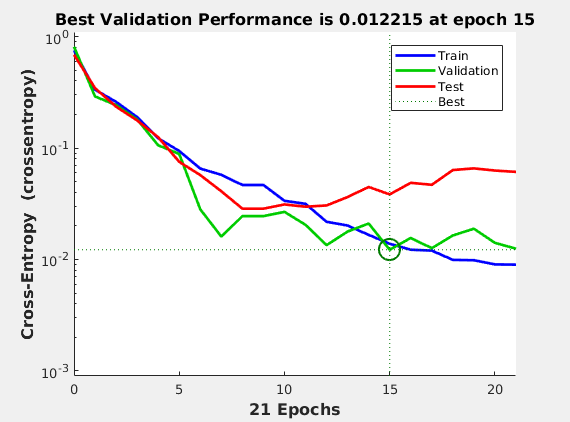

figure(2), plotperform(info_entrenamiento)

¿Qué ocurre cuando el entrenamiento alcanza el óptimo de validación?

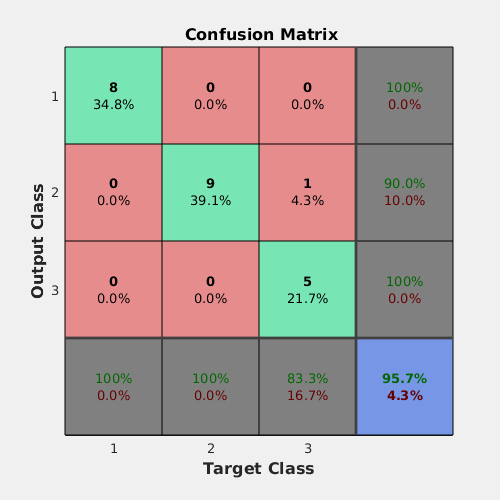

figure(3), plotconfusion(clasificacion_test,clasificacion_test_red);

# 4) Utiliza la red para clasificar una flor Iris en base a sus características

Con un ejemplar desconocido para la red (no utilizado durante su entrenamiento), ¿a qué clase pertenece realmente?

[flor_caracteristicas,clasificacion_flor]=obtener_ejemplar

flor_caracteristicas =     4.8000
    3.0000
    1.4000
    0.3000


clasificacion_flor =      1
     0
     0


tipo_flor(clasificacion_flor)

ans = "setosa"

flor_clasificacion_red=red_entrenada(flor_caracteristicas)

flor_clasificacion_red =     0.9979
    0.0021
    0.0000


tipo_flor(flor_clasificacion_red)

ans = "setosa"